clear; close all; clc;

**Question 4: Iterative soft-thresholding for X-ray tomography**

Define an initial iterate

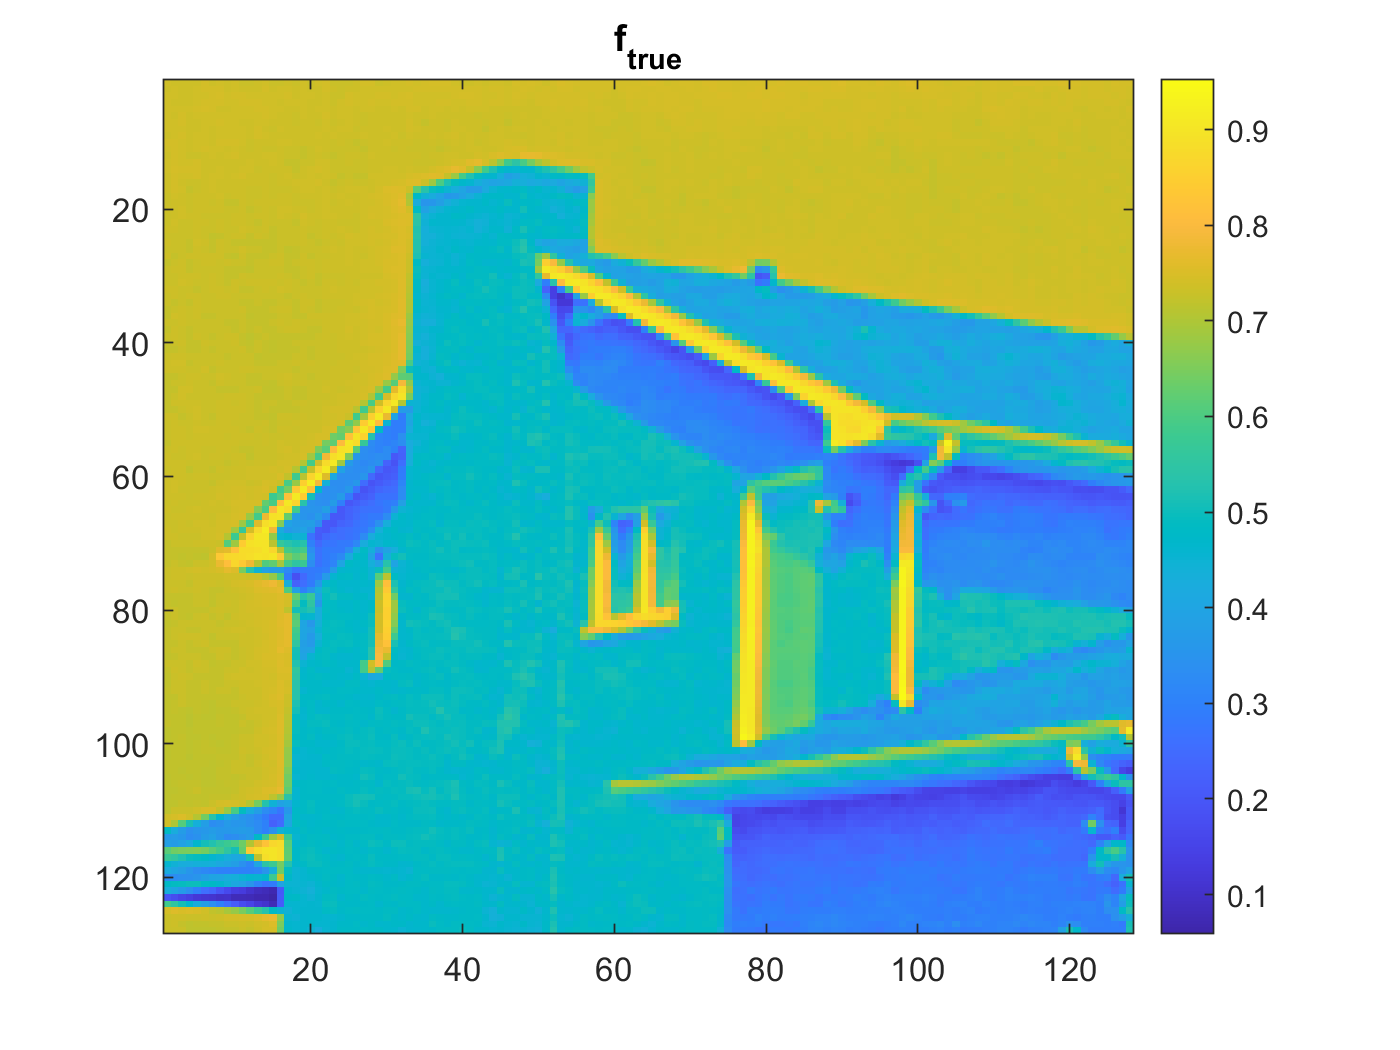

f_true = im2double(imread('house.png'));

f_noisy = f_true + (randn(size(f_true)) * 0.1);

figure; imagesc(f_true); colorbar; title('f_{true}');

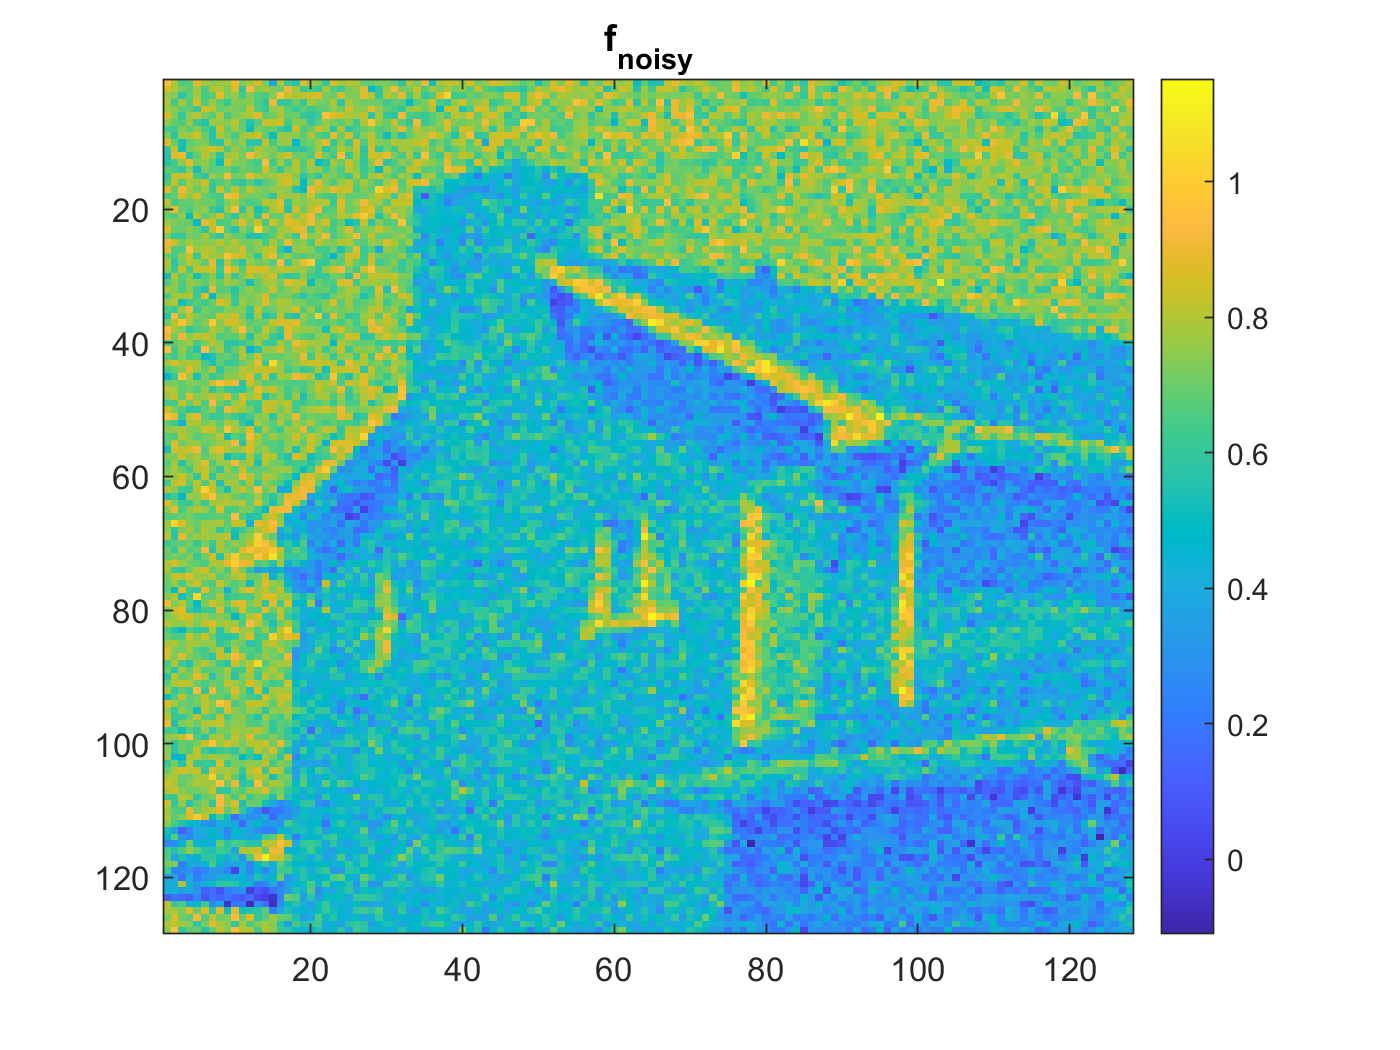

figure; imagesc(f_noisy); colorbar; title('f_{noisy}');

Iterative algorithm

[a, h, v, d] = haart2(f_noisy);

range = 1 : 3;

iterations = 5;

for i = 1 : iterations
    t_val = determine_threshold(h, v, d, range, 0.87+(i/100.0))

    [ht, vt, dt] = thresholdFunction(h, v, d, range, t_val, 's');
    
    for i = 1 : numel(range)
        h{i} = h{i} + ht{i};
        v{i} = v{i} + vt{i};
        d{i} = d{i} + dt{i};
    end
    
    denoised = ihaart2(a, h, v, d);
    
    sum(sum((f_true - denoised)^2))
end

index = 14192

t_val = -0.1765

ans = 39.1192

index = 14353

t_val = 0.5406

ans = 884.8346

index = 14515

t_val = 0.5670

ans = 4.0647e+03

index = 14676

t_val = -0.6234

ans = 2.3783e+04

index = 14837

t_val = 2.0091

ans = 7.9537e+04

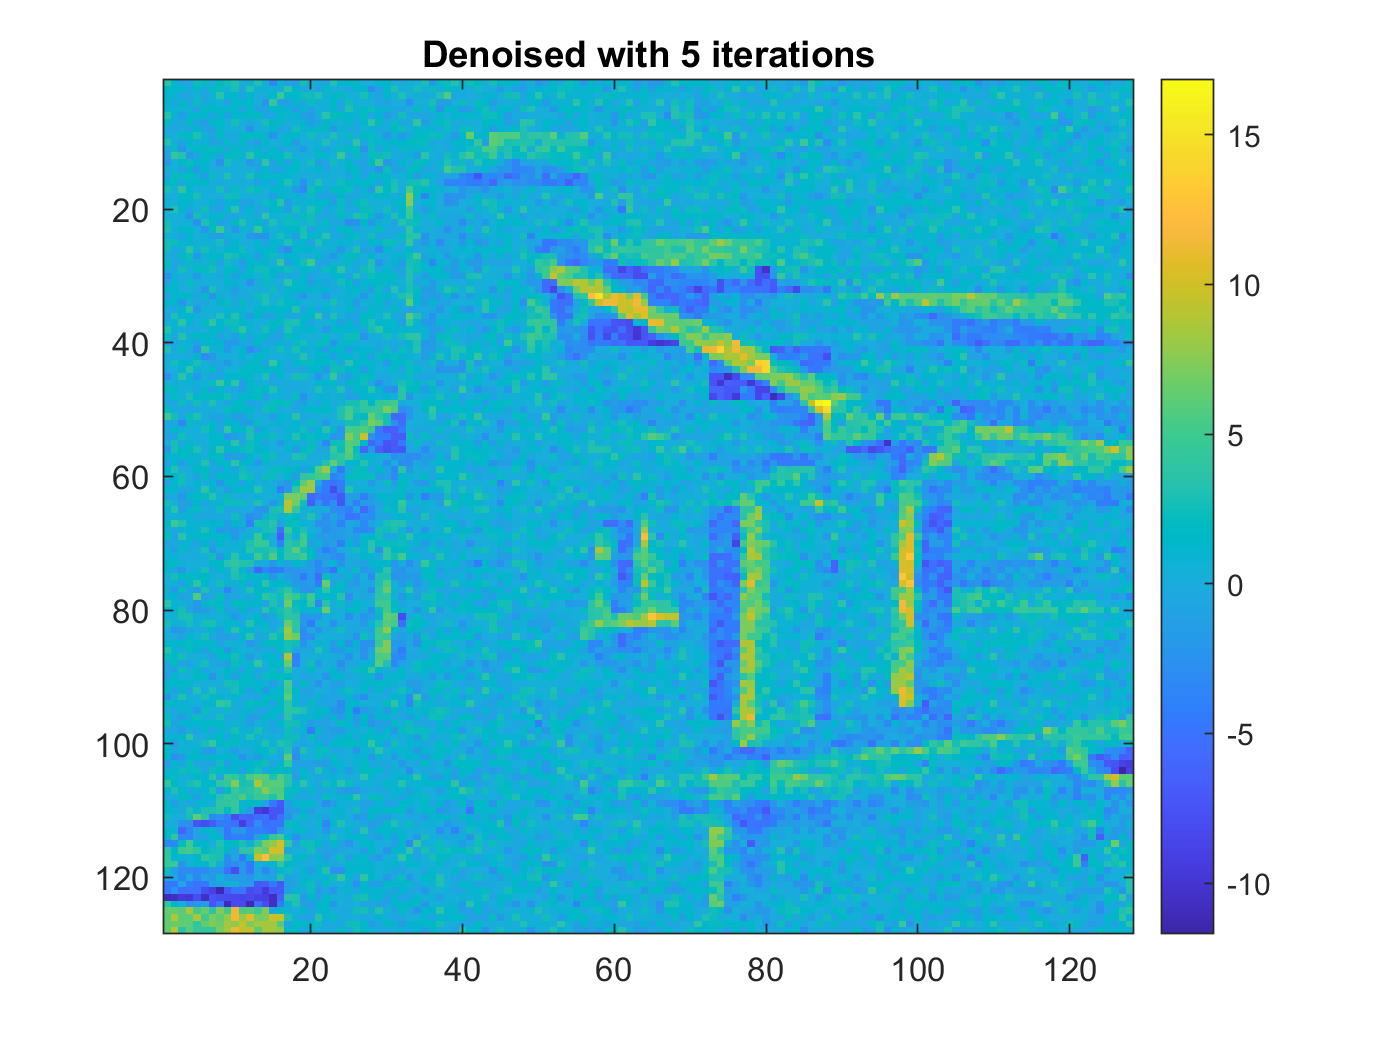

figure; imagesc(denoised); colorbar; title(['Denoised with ' num2str(iterations) ' iterations']);